## Playing around with data to learn more about PCA

Author: Emily J King, https://www.math.colostate.edu/~king/

Note: This lab does not make use of the Statistics and Machine Learning Toolbox, which has a pca function. If you look at the documentation of that function, then applying it to the data matrix X'  yields the outputs coeff, which is the U of the SVD of the zero-centered data X_c, and score, which is V*S' of the SVD of the zero-centered data.

#### Generating noisy data around the line y=2x+4 in R^2 and then plotting the data.  

By changing m and sigma, you may change the slope and noise level, respectively, of the data.

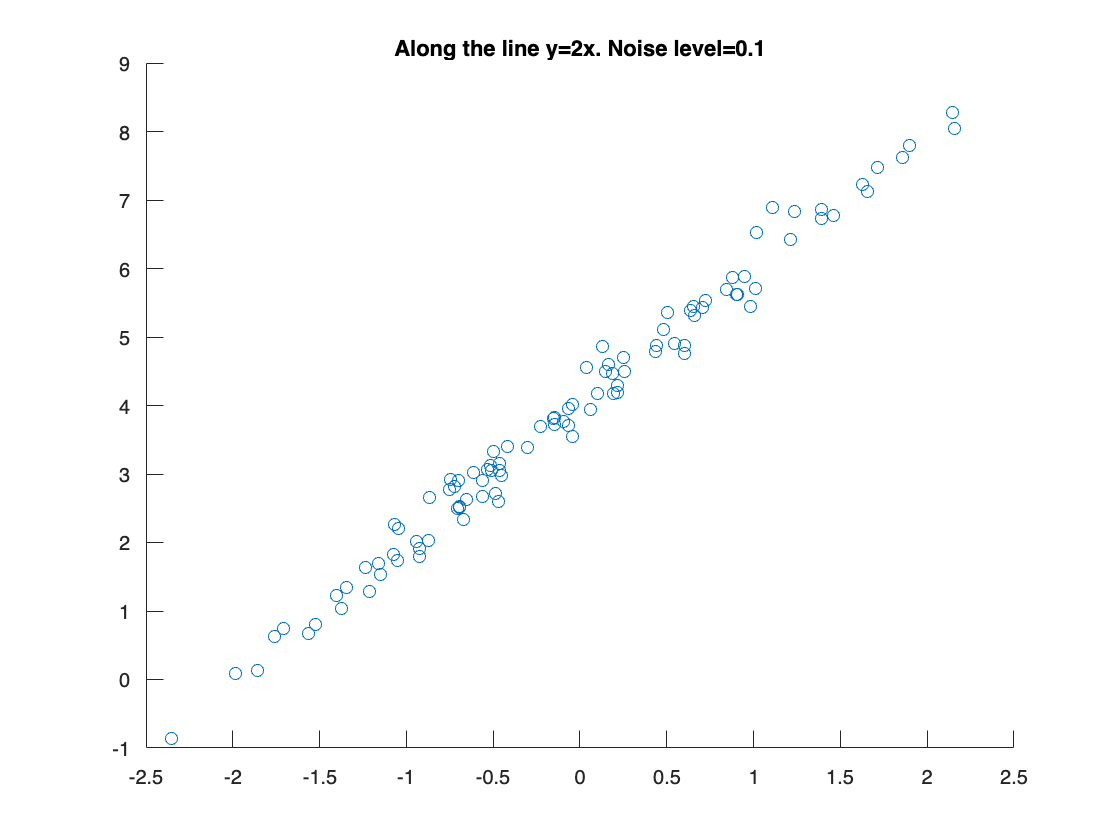

m=2; % slope of the line
b=4; % y-intercept of the line
sigma=0.1; % noise level
X=makepcadata([1;m],100,sigma)+[0;b];

figure, scatter(X(1,:),X(2,:)), title(['Along the line y=',num2str(m),'x. Noise level=',num2str(sigma)])

We compute principal component analysis (PCA) of the data by forming the data matrix with data points as columns, centering the data, and computing the singular value decomposition (SVD) of the centered data matrix.

Xc=X-mean(X,2); 
[U,S,V]=svd(Xc); 
disp(['The singular values are: ' num2str(diag(S)')])

The singular values are: 22.1788      1.02484


disp(['The normalized singular values are: ' num2str(diag(S.^2)'/norm(diag(S))^2)])

The normalized singular values are: 0.99787   0.0021307


disp('The (unit norm) principal components are the columns of')

The (unit norm) principal components are the columns of


disp(U)  

   -0.4437    0.8962
   -0.8962   -0.4437



disp(['Double checking that the SVD is indeed correct' newline 'by showing the Frobenius norm of the difference' newline 'between the centered data matrix and USV^T' newline 'is close to zero. The norm is ' num2str(norm(Xc-U*S*V','fro')) '.'])

Double checking that the SVD is indeed correct
by showing the Frobenius norm of the difference
between the centered data matrix and USV^T
is close to zero. The norm is 2.0083e-14.


We notice that the first singular value is much larger than the second.  This suggests that the points are modeled well by a one-dimensional affine subspace (i.e., a line).  This makes sense as the data was generated as points from a line with added noise.

To project the data onto PCA affine line of best fit, we project each of the centered points onto the span of the first column of U, then add back in the average values which had been subtracted off when centering.

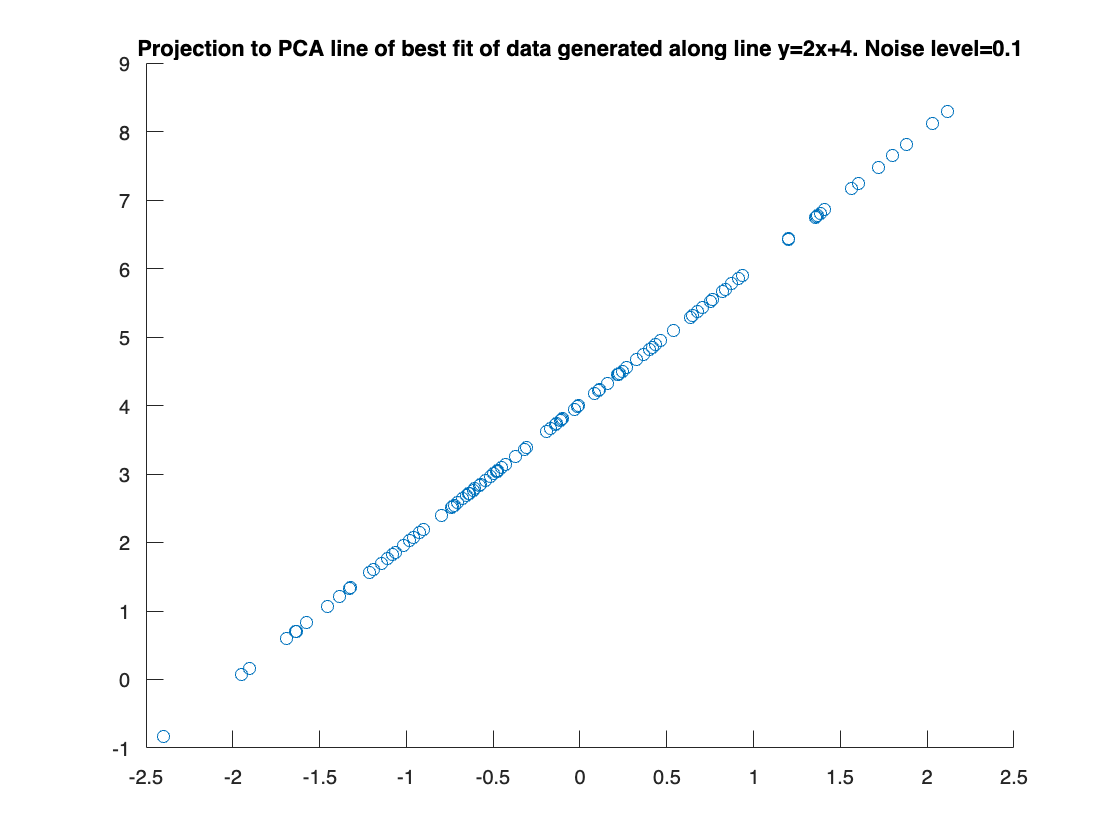

Ut=U(:,1); % truncate to first column
St=S(1,1); % truncate to upper left entry
Vt=V(:,1); % truncate to first column

Xt = Ut*St*Vt'+mean(X,2); 
figure, scatter(Xt(1,:),Xt(2,:)), title(['Projection to PCA line of best fit of data generated along line y=',num2str(m),'x+',num2str(b),'. Noise level=',num2str(sigma)])

We compare the slope of the line fit by PCA with the slope of the line used to generate the data.

disp(['The slope of the line used to generate the data is ' num2str(m) ',' newline 'while the slope of the fitted line is ' num2str(U(2,1)/U(1,1))])

The slope of the line used to generate the data is 2,
while the slope of the fitted line is 2.0199


Play around with the slope, intercept, and noise level of the generated data in the model above.  In particular, note how changes to the noise level affect the relative sizes of the singular values as well as the slope of the fitted line.

#### Generating data by randomly drawing points from a fixed two-dimensional linear subspace in R^4 and then adding Gaussian noise.  

We can't visualize points in R^4, so we will only be able to plot projections of our data.

sigma=0.1; % noise level
[W,~]=qr(randn(4,2),"econ"); % orthonormal basis of a random 2D subspace of R^4
X=makepcadata(W,1000,sigma);

We compute principal component analysis (PCA) of the data by forming the data matrix with data points as columns, centering the data, and computing the singular value decomposition (SVD) of the centered data matrix.

Xc=X-mean(X,2); 
[U,S,V]=svd(Xc); 
disp(['The singular values are: ' num2str(diag(S)')])

The singular values are: 32.9523      31.9067      3.35542      3.13513


disp(['The normalized singular values are: ' num2str(diag(S.^2)'/norm(diag(S))^2)])

The normalized singular values are: 0.511     0.47908   0.0052983   0.0046255


disp('The (unit norm) principal components are the columns of')

The (unit norm) principal components are the columns of


disp(U)  

    0.5473   -0.8311   -0.0978    0.0132
   -0.5528   -0.4470    0.7032   -0.0081
   -0.0189   -0.0234   -0.0412   -0.9987
   -0.6281   -0.3301   -0.7030    0.0486



We notice that the first two singular values are much larger than the last two.  This suggests that the points are modeled well by a two-dimensional affine subspace (i.e., a plane).

To project the data onto PCA affine plane of best fit, we project each of the centered points onto the span of the first two columns of U, then add back in the average values which had been subtracted off when centering.   If we just project down to the span of the first two columns of U, the resulting numbers are called the scores.

However, we cannot visualize this two-dimensional subspace of R^4.  Thus, we visualize a projection of the data onto R^2 by using the inner products of the centered data with the first two columns of U as the coordinates in R^2.  The points are randomly spread in this subspace due to the way that `makepcadata` generates the random data sets, as seen in the plot.

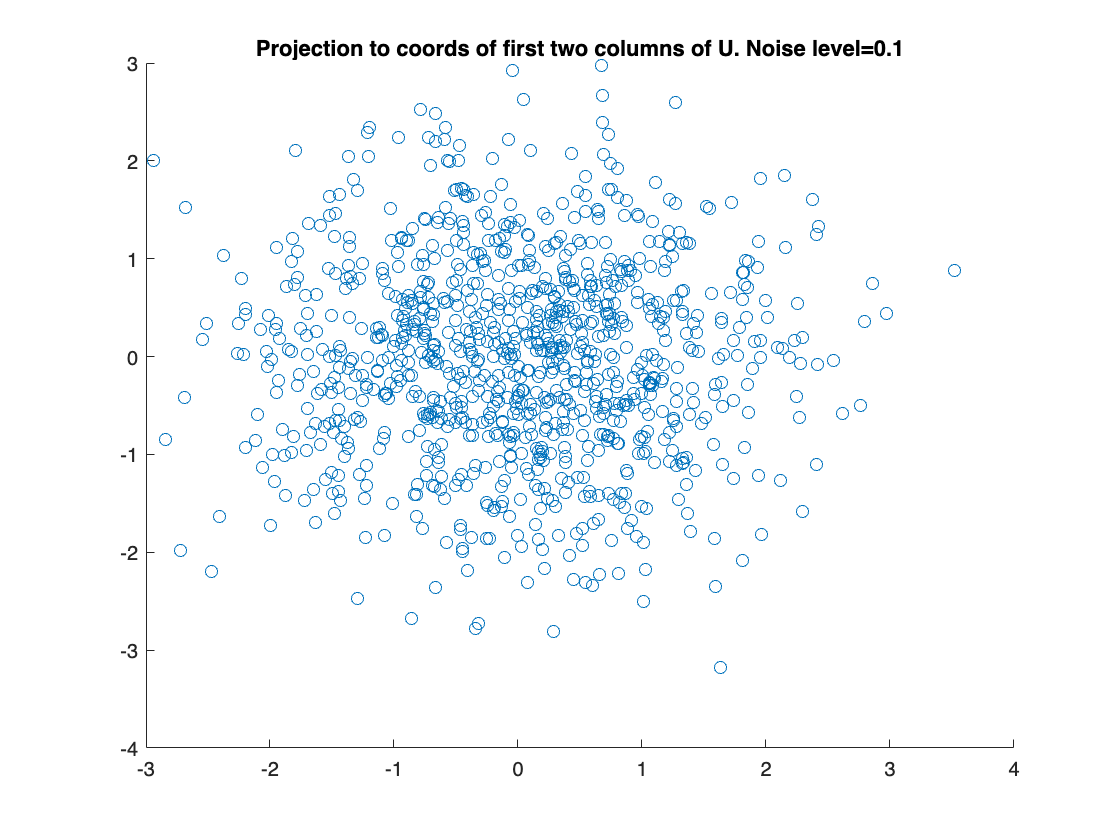

Ut=U(:,1:2); % truncate to first two columns
St=S(1:2,1:2); % truncate to upper left 2x2 entries
Vt=V(:,1:2); % truncate to first two columns

Xt = St*Vt';  
figure, scatter(Xt(1,:),Xt(2,:)), title(['Projection to coords of first two columns of U. Noise level=',num2str(sigma)])

We also compute the covariance matrices of the projections of the centered points onto the subspace spanned by the first two columns of U and onto the last two columns. Note that the variances are much  larger for the projection onto the first two columns of U; this corresponds to the intuition that those directions are responsible for most of the variance of the points.  Since the columns of U are orthogonal, the covariances are 0 in all cases.

disp(['The covariance matrix of the projection of the points' newline 'onto the first two columns of U:'])

The covariance matrix of the projection of the points
onto the first two columns of U:


disp(cov(Xt'))

    1.0869   -0.0000
   -0.0000    1.0191



disp(['The covariance matrix of the projection of the points' newline 'onto the last two columns of U:'])

The covariance matrix of the projection of the points
onto the last two columns of U:


disp(cov(V(:,3:4)*S(3:4,3:4)))

    0.0113   -0.0000
   -0.0000    0.0098



Finally, we compute the Frobenius distance between the orthgonal projection onto the two-dimensional subspace of R^4 used to generate the points and orthogonal projection onto the two-dimensional subspace found by PCA.

disp(['The Frobenius distance between' newline 'the projection onto the two-dimensonal subspace' newline 'used to generate the data and the' newline 'subspace fit by PCA is ' num2str(norm(Ut*Ut'-W*W','fro'))])

The Frobenius distance between
the projection onto the two-dimensonal subspace
used to generate the data and the
subspace fit by PCA is 0.0082867


Play around with the noise level of the generated data in the model above.  In particular, note how changes to the noise level affect the relative sizes of the singular values as well as the Frobenius distance between the projections onto the original and learned subspaces.

#### Generating data by first generating a random four-dimensional subspace of R^50 and then generating data by randomly drawing points from this subspace and adding Gaussian noise.  

We can't visualize points four-dimensional spaces, let alone R^50, so we won't plot the points.

sigma=0.1; % noise level
[W,~]=qr(randn(50,4),"econ"); % orthonormal basis of a random 4D subspace of R^50
X=makepcadata(W,1000,sigma); 

We compute principal component analysis (PCA) of the data by forming the data matrix with data points as columns, centering the data, and computing the singular value decomposition (SVD) of the centered data matrix.

Xc=X-mean(X,2); 
[U,S,V]=svd(Xc);  

Since there are 50 singular values, it is more helpful to look at a plot of them rather than a list.  Such a plot of singular values is called a scree plot.

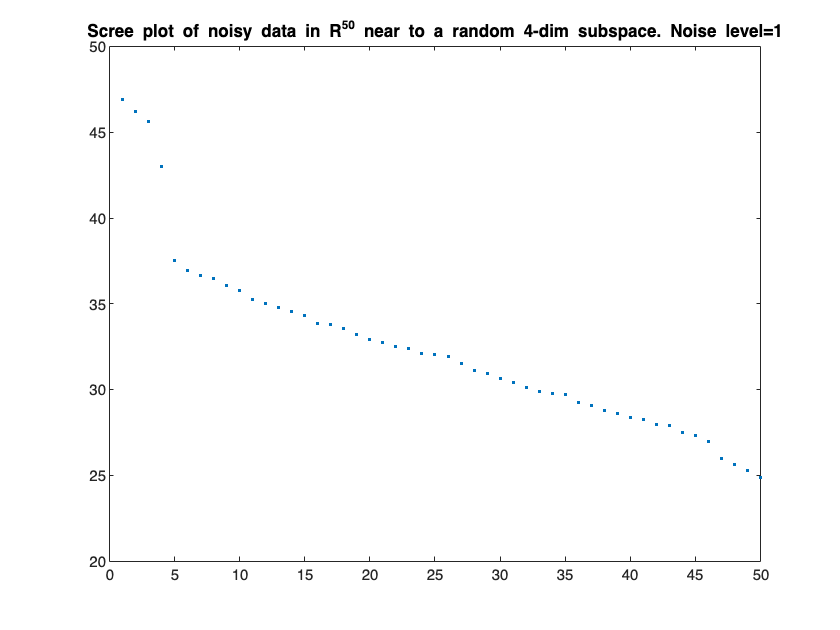

figure, plot(diag(S),'.'), title(['Scree plot of noisy data in R^{50} near to a random 4-dim subspace. Noise level=',num2str(sigma)])

We notice that the first four singular values are much larger than the remaining 46.  This suggests that the points are modeled well by a four-dimensional subspace.

We can't really plot points or their projections in a meaningful way, but we can compute the 50 variances of the data projected onto the 50 difference columns of U.

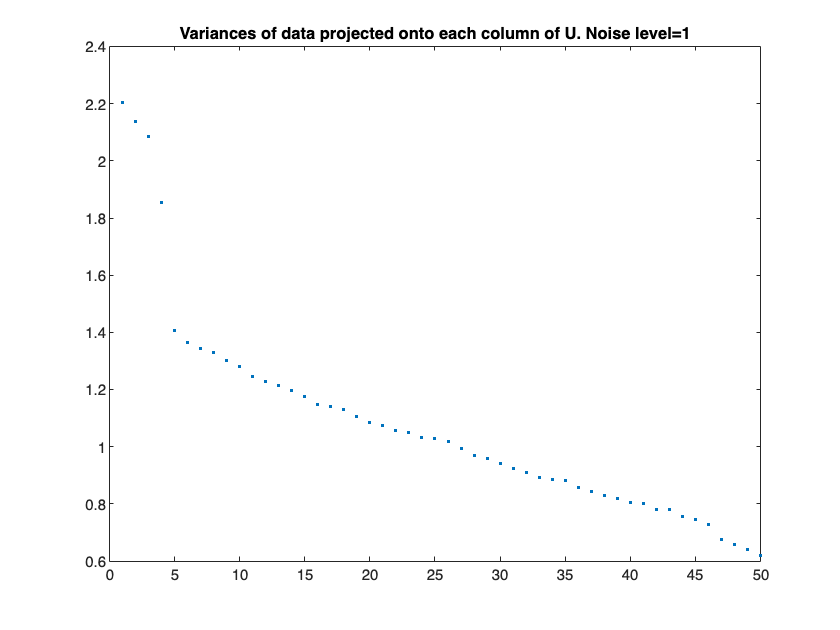

figure, plot(var(V*S'),'.'), title(['Variances of data projected onto each column of U. Noise level=',num2str(sigma)])

Note the similarity of the shape of the scree plot and the plot of the variances.  This is because they are both giving the same message: that the subspace spanned by the first four columns of U describes most of the variance of the points.

Finally, we compute the Frobenius distance between the orthgonal projection onto the random four-dimensional subspace of R^50 used to generate the points and orthogonal projection onto the four-dimensional subspace found by PCA.

Ut=U(:,1:4); % truncate to first four columns

disp(['The Frobenius distance between' newline 'the projection onto the four-dimensonal subspace' newline 'used to generate the data and the' newline 'subspace fit by PCA is ' num2str(norm(Ut*Ut'-W*W','fro'))])

The Frobenius distance between
the projection onto the four-dimensonal subspace
used to generate the data and the
subspace fit by PCA is 0.80675


Play around with the noise level of the generated data in the model above.  In particular, note how changes to the noise level affect the relative sizes of the singular values as well as the Frobenius distance between the projections onto the original and learned subspaces.

function X=makepcadata(basis,numpts,sigma)
% makepcadata
% Generate random points in a subspace and add random noise. 
%
% INPUTS:
% basis: An NxK matrix whose columns are a basis of a K-dimensional
%   subspace of R^N
% numpts: How many points to generate
% sigma: The noise level. A higher number means the generated points are
%   spread more from the subspace.
%
% OUTPUTS:
% X: A Nx(numpts) matrix whose rows are the randomly generated data points.
%  This matrix is not yet zero-centered.
%
% AUTHOR:
% Emily J. King

X=(basis*randn(size(basis,2),numpts)+sigma*randn(size(basis,1),numpts));

end
